# EasyPlot Demo

Display the data as two heatmaps

Create data: two 10x10 matrices

rng(1); % set the random seed
% x1 has a larger mean than x2
x1 = rand(10)-0.3;
x2 = rand(10)-0.7;

Create a figure with two axes

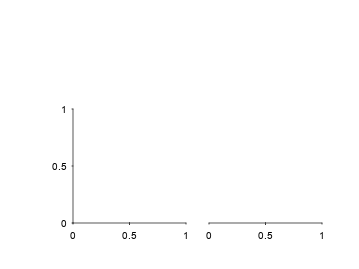

fig = EasyPlot.figure(); % create a figure in EasyPlot style

ax1 = EasyPlot.axes(fig,... % create an axes in EasyPlot style
    'Height', 3,... % in centimeters
    'Width', 3,... 
    'MarginBottom', 0.8); % the space under the axes

% create the second axes on the right of the first axes
ax2 = EasyPlot.createAxesAgainstAxes(fig, ax1, 'right',...
    'YAxisVisible', 'off'); % hide the Y axis for the right-side axes

Plot the matrices the same way as in MATLAB

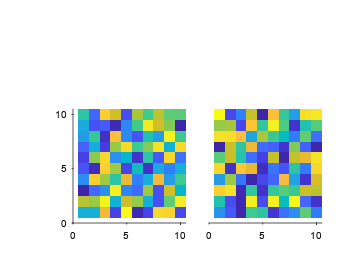

imagesc(ax1, x1);
imagesc(ax2, x2);

Set multiple "xlabel" and "ylabel" together

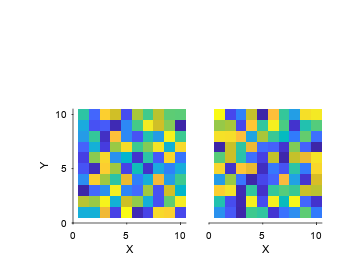

EasyPlot.setXLabelRow({ax1, ax2}, 'X');
EasyPlot.setYLabelRow({ax1, ax2}, 'Y');

Set the X / Y limits of the multiple axes together

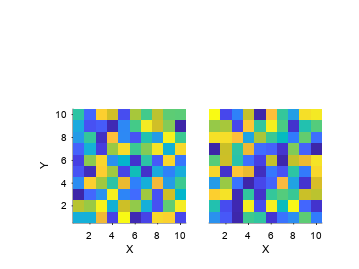

EasyPlot.setXLim({ax1, ax2}, [0.5,10.5]);
EasyPlot.setYLim({ax1, ax2}, [0.5,10.5]);

Set the same color limits for the two heatmaps in order to compare them directly

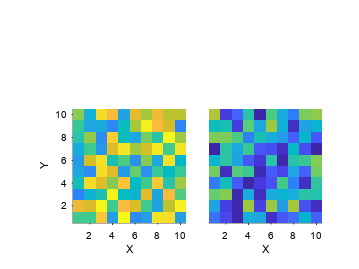

% set the color limits that covers both axes
EasyPlot.setCLim({ax1, ax2}, 'largest');

Set the colormap and colorbar

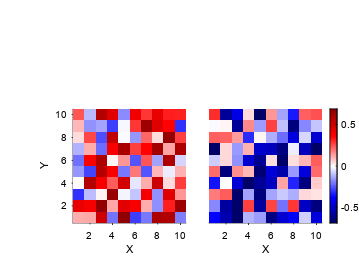

% use the same colormap for both axes and set the white color for zero
EasyPlot.colormap({ax1, ax2}, EasyPlot.ColorMap.Diverging.seismic,...
    'zeroCenter', 'on'); % set the white color for zero
EasyPlot.colorbar(ax2,...
    'label', 'Color bar',... % colorbar label
    'MarginRight', 1); % the space on the right

Mark the axes

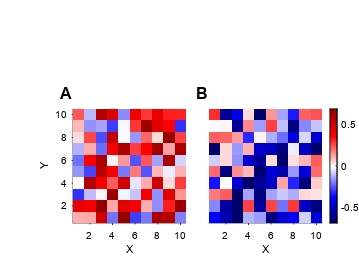

EasyPlot.markAxes(fig, {ax1, ax2}, {'A','B'},...
    'xShift', 0.5,...
    'MarginTop', 0);

Export the figure

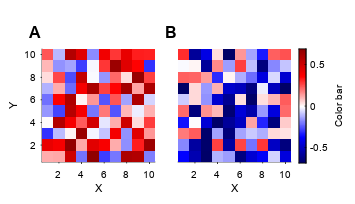

EasyPlot.cropFigure(fig); % crop the figure to get the proper figure size
EasyPlot.exportFigure(fig, 'demo.png');